L_i = 1.2e-3;        % H
L_g = 0.7e-3;        % H
C_f = 9e-6;          % F
R_d = 8;             % Ohms

T_S = 1e-4;          % s

s = tf('s');
T_D = (1/(1+T_S*s));
G_F = ((1/(L_i*s))*(((s^2)+(s*R_d/L_g)+(1/(L_g*C_f)))/((s^2)+(s*((L_i*R_d+L_g*R_d)/(L_i*L_g)))+((L_i+L_g)/(L_i*L_g*C_f)))))*T_D;

omega_0 = 2*pi*50;   % rad/sec
omega_c = 0.5;       % rad/sec)

w1 = 100000;
w2 = 5;
w3 = 25;
% cost function
obj = @(x) (...
           (w1*(abs(stepinfo(feedback(G_F*(x(1)+x(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2)))),1)).RiseTime))) + ...
           (w2*(abs(stepinfo(feedback(G_F*(x(1)+x(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2)))),1)).Overshoot))) + ...
           (w3*(...
           abs(20*log10(bode(G_F*(x(1)+x(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2)))),omega_0))-68) + ...
           abs(20*log10(bode(G_F*(x(1)+x(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2)))),omega_0-100*omega_c))-30) ...
           )));

% Bounds for the optimization
lb = [0,0];
ub = [10000,10000];

% Starting point for the optimization
x0 = [1,1];

% Optimization
options = optimoptions('fmincon','Display','iter','MaxIter',100,'TolFun',1e-12);
x = fmincon(obj,x0,[],[],[],[],lb,ub,[],options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.431570e+03    0.000e+00    7.368e+02
    1       6    1.300120e+03    0.000e+00    2.663e-01    6.774e+02
    2       9    1.300020e+03    0.000e+00    2.663e-01    3.147e-01
    3      12    1.299520e+03    0.000e+00    2.661e-01    1.575e+00
    4      15    1.297021e+03    0.000e+00    2.647e-01    7.875e+00
    5      18    1.284461e+03    0.000e+00    2.698e-01    3.940e+01
    6      21    1.219259e+03    0.000e+00    2.737e-01    1.982e+02
    7      24    5.879033e+02    0.000e+00    3.195e+00    1.054e+03
    8      27    4.566383e+02    0.000e+00    2.035e+02    2.288e+02
    9      31    3.576213e+02    0.000e+00    5.661e+00    1.120e+02
   10      34    3.488226e+02    0.000e+00    6.166e+00    3.821e+00
   11      37    2.998084e+02    0.000e+00    5.950e+00    2.045e+01
   12      40    1.474506e+02    0.000e+00    3


K_P = x(1)

K_P = 8.0187

K_PR = x(2)

K_PR = 1.4924e+03


% Closing the loop:
G = feedback(G_F*(K_P+K_PR*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2)))),1);

K_P_fp = 6.8

K_P_fp = 6.8000

K_PR_fp = 1498.72

K_PR_fp = 1.4987e+03

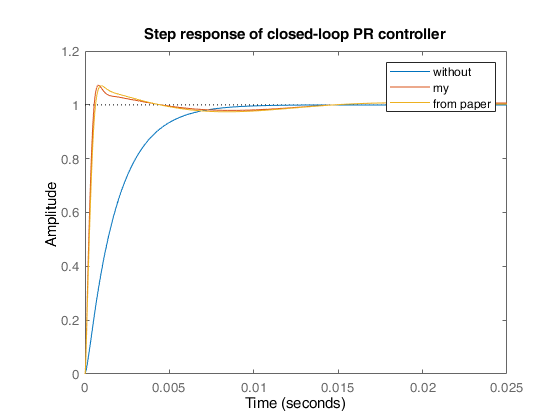


% Closing the loop:
G_fp = feedback(G_F*(K_P_fp+K_PR_fp*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2)))),1);

% Plotting the step response of the closed-loop system:
figure
step(feedback(G_F,1),G,G_fp)
title('Step response of closed-loop PR controller')
legend("without","my","from paper");

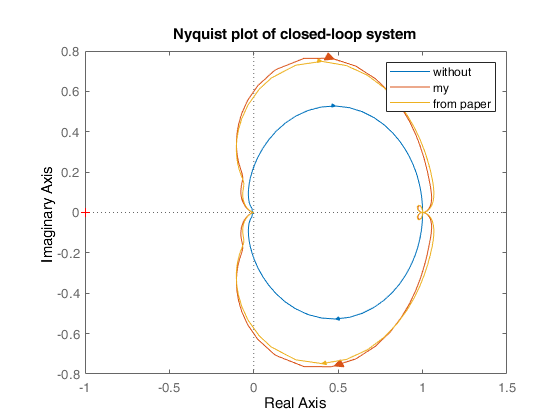

nyquist(feedback(G_F,1),G,G_fp)
legend("without","my","from paper");
title('Nyquist plot of closed-loop system')

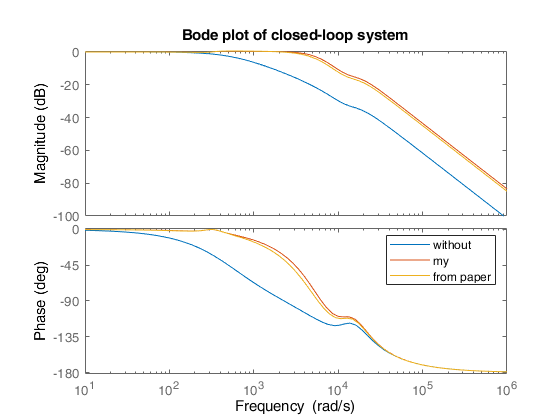

bode(feedback(G_F,1),G,G_fp)
legend("without","my","from paper");
title('Bode plot of closed-loop system')

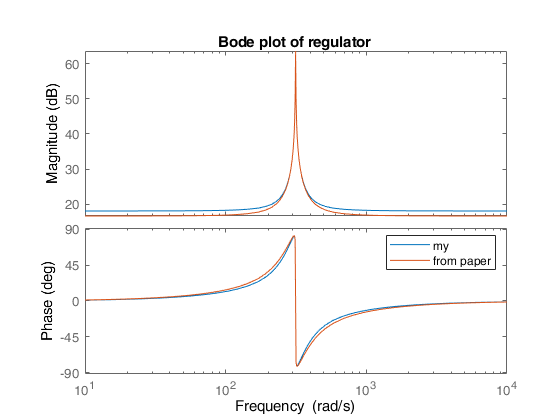


bode(K_P+K_PR*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2))) ...
    ,K_P_fp+K_PR_fp*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2))));

legend("my","from paper");
title('Bode plot of regulator')